## `Modello matematico`

m1=1;
m2=1.5;
M=0.3;
R=0.2;
k1=5;
k2=5;
k3=6;
b=2;
J=M*R^2/2;
const=M*R+J/R;

A=[ 0   1    0   0  0   0;
    -k1/m1 -b/m1 k1/m1*R  b*R/m1 0   0;
    0   0   0    1  0   0;
    k1/const  b/const -(k1*R+k3*R)/const -b*R/const k2/const 0;
    0   0    0   0  0  1;
    0   0 k2*R/m2 0 -(k3+k2)/m2 0];

B=[0 0 0 0 0 k3/m2;
    0 0 0 2/const 0 0]';

C=[1 0 0 0 0 0;
    0 0 0 0 1 0];

D=zeros(2);

x0=[0 0.1 0 0.02 0 0.5];

eig(A)

ans =   -2.8525 + 3.8453i
  -2.8525 - 3.8453i
  -0.3085 + 2.7899i
  -0.3085 - 2.7899i
  -0.0612 + 1.2953i
  -0.0612 - 1.2953i


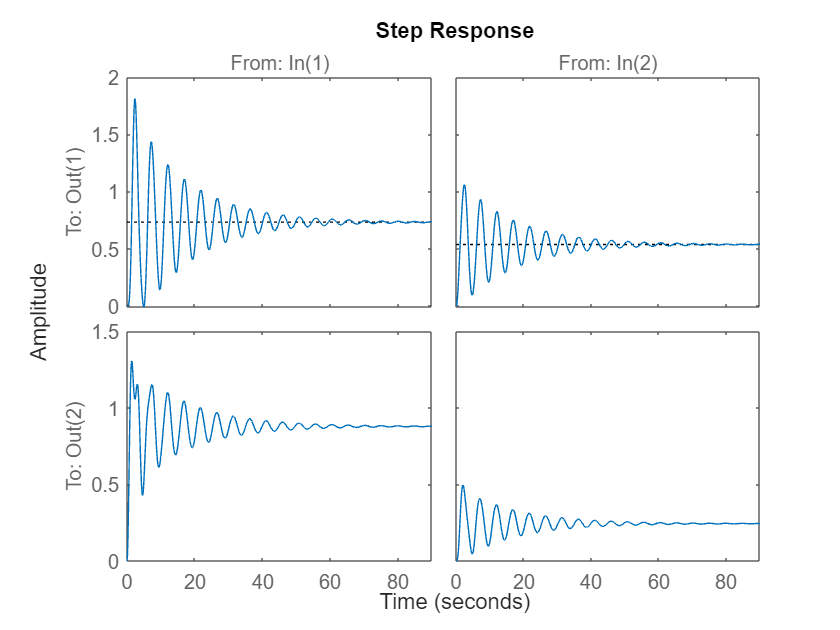

sys=ss(A,B,C,D);
figure
step(sys);

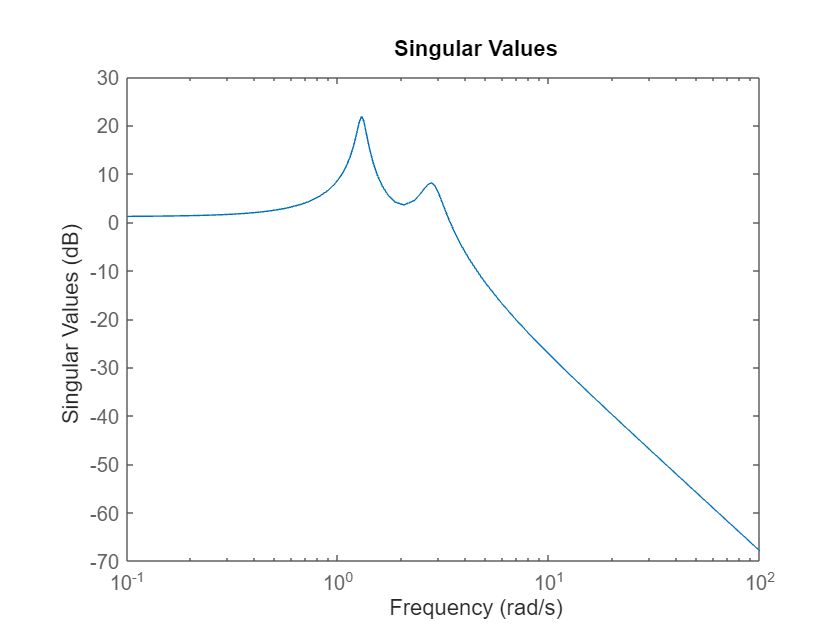

figure
sigma(sys(:,1))

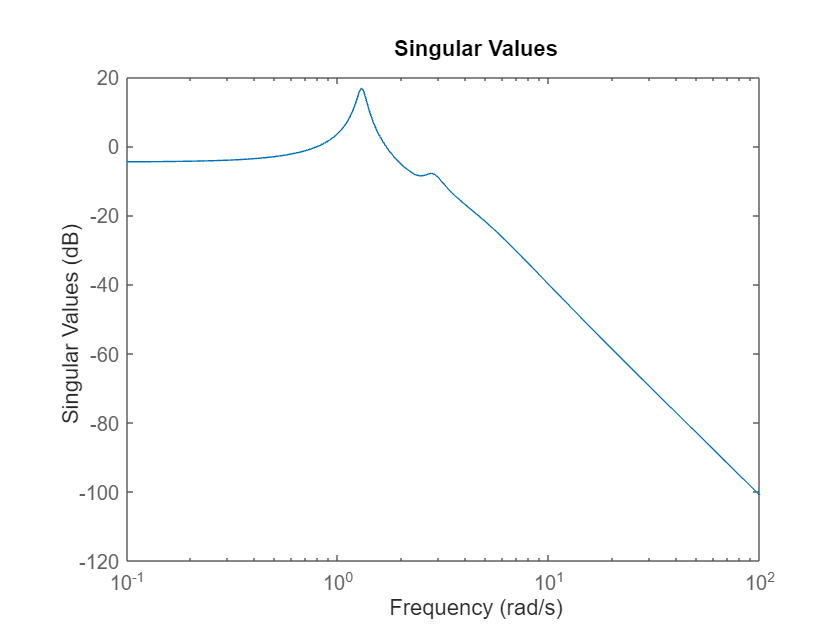

sigma(sys(:,2))

hinfnorm(sys(:,1))

ans = 12.3446

hinfnorm(sys(:,2))

ans = 6.9349

## `Controllabilità e Osservabilità`

ctr=ctrb(A,B);
rank(ctr)       %risulta completamente controllabile

ans = 6


obs=obsv(A,C);
rank(obs)       %risulta completamente osservabile

ans = 6

## Azione integrale + assgnamento

ctr_d=ctrb(A,B(:,1));
rank(ctr_d)         %risulta completamente controllabile

ans = 6

obs_d=obsv(A,C(1,:));
rank(obs_d)  

ans = 6

% creo l'impianto aumentato inserendo 1 integratore per avere errore a
% regime nullo

Aaum=[A zeros(6,1);
   -C(1,:) 0];
Baum=[B;zeros(1,2)];
Caum=[C zeros(2,1)];
Daum=D;

sysAum=ss(Aaum,Baum,Caum,Daum);
rank(ctrb(Aaum,Baum(:,1)))      %risulta completamente controllabile

ans = 7

PO=10;
Ta=8;
zita=abs(log(PO/100))/(sqrt(pi^2+log(PO/100)^2));
wn=4/(zita*Ta);
p=roots([1 2*zita*wn wn^2])';
% a questi aggiungo gli altri 5 poli ad alte frequenze:
Poli=[p real(p(1)*10) real(p(1)*11+1) real(p(1)*11+2) real(p(1)*11+3) real(p(1)*11+4)]

Poli =   -0.5000 - 0.6822i  -0.5000 + 0.6822i  -5.0000 + 0.0000i  -4.5000 + 0.0000i  -3.5000 + 0.0000i  -2.5000 + 0.0000i  -1.5000 + 0.0000i


Kaum=place(Aaum,Baum(:,1),Poli)

Kaum =    -0.6423    1.5503   -0.6958   -0.2511    4.4921    2.8889   -0.9507


eig(Aaum-Baum(:,1)*Kaum)

ans =   -5.0000 + 0.0000i
  -4.5000 + 0.0000i
  -3.5000 + 0.0000i
  -0.5000 + 0.6822i
  -0.5000 - 0.6822i
  -2.5000 + 0.0000i
  -1.5000 + 0.0000i


Kpaum=Kaum(:,1:6)

Kpaum =    -0.6423    1.5503   -0.6958   -0.2511    4.4921    2.8889


Kiaum=Kaum(:,7)

Kiaum = -0.9507

## Osservatore

obs=obsv(A,C(1,:));
rank(obs) 

ans = 6

Poss=[-18 -19 -21 -20 -22 -24]

Poss =    -18   -19   -21   -20   -22   -24


L=-place(A',C(1,:)',Poss)';
Aoss=A+L*C(1,:);
Boss=[B -L];
Coss=eye(6);
Doss=zeros(6,3);
oss=ss(Aoss,Boss,Coss,Doss);
eig(Aoss)

ans =   -24.0000
  -22.0000
  -21.0000
  -20.0000
  -19.0000
  -18.0000


## `Azione integrale + LQR`

% a questo punto ricaviamo la matrice di retroazione K attraverso il
% controllo LQR

Qy=8;
Qi=80;
Q=[C'*Qy*C zeros(6,1);
    zeros(1,6) Qi];
R=15;

[Klq,P,e]=lqr(sysAum(:,1),Q,R);
Klq

Klq =     1.8938    1.3901   -0.1314    0.0805    1.1217    0.7489   -2.3094


P 

P =    58.3498   27.3253   -2.1466    1.4919   21.9112    7.1018  -76.6418
   27.3253   16.3480   -1.6963    0.8939   12.2333    5.2130  -34.7165
   -2.1466   -1.6963    0.2477   -0.0881   -1.1833   -0.4927    2.9091
    1.4919    0.8939   -0.0881    0.0497    0.6531    0.3018   -1.8426
   21.9112   12.2333   -1.1833    0.6531   16.4283    4.2065  -25.9431
    7.1018    5.2130   -0.4927    0.3018    4.2065    2.8084   -8.6603
  -76.6418  -34.7165    2.9091   -1.8426  -25.9431   -8.6603  136.8190


e

e =   -0.6266 + 2.9181i
  -0.6266 - 2.9181i
  -0.8138 + 1.5065i
  -0.8138 - 1.5065i
  -0.8580 + 0.0000i
  -2.8506 + 3.8440i
  -2.8506 - 3.8440i


% adesso divido il guadagno in due parti: retroazione + integratore
Klqp=Klq(:,1:6)

Klqp =     1.8938    1.3901   -0.1314    0.0805    1.1217    0.7489


Klqi=Klq(:,7)

Klqi = -2.3094

ClLQ=closedLoop(A,B,eye(6),zeros(6,2),Kaum)

ClLQ =
 
  A = 
           x1      x2      x3      x4      x5      x6      x7
   x1       0       1       0       0       0       0       0
   x2      -5      -2       1     0.4       0       0       0
   x3       0       0       0       1       0       0       0
   x4   55.56   22.22  -24.44  -4.444   55.56       0       0
   x5       0       0       0       0       0       1       0
   x6   2.569  -6.201    3.45   1.005   -25.3  -11.56   3.803
   x7      -1       0       0       0       0       0       0
 
  B = 
          Ref  ForceW
   x1       0       0
   x2       0       0
   x3       0       0
   x4       0   22.22
   x5       0       0
   x6       0       0
   x7       1       0
 
  C = 
                  x1      x2      x3      x4      x5      x6      x7
   Pos1            1       0       0       0       0       0       0
   Vel1            0       1       0       0       0       0       0
   Pos_ruota       0       0       1       0       0       0       0
   Vel_ruota      

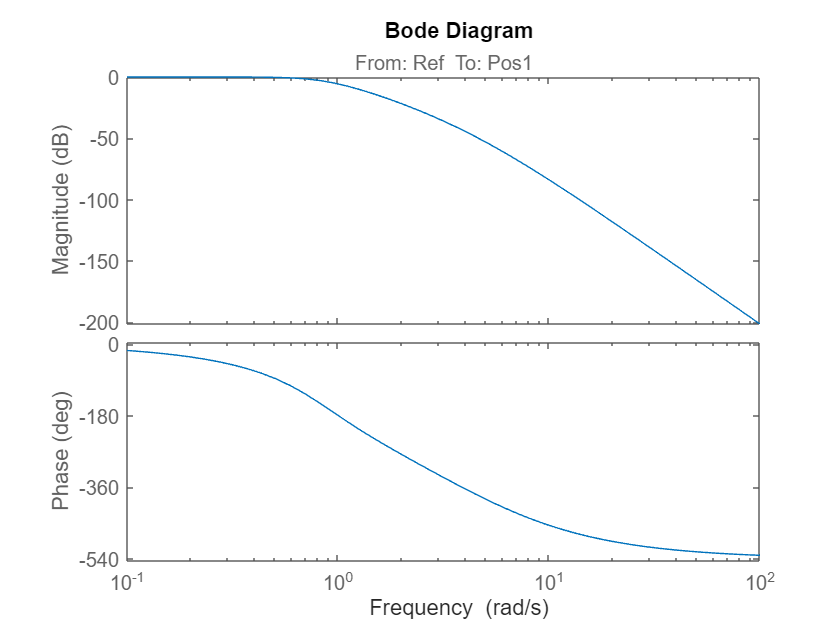

bode(ClLQ(1,1))

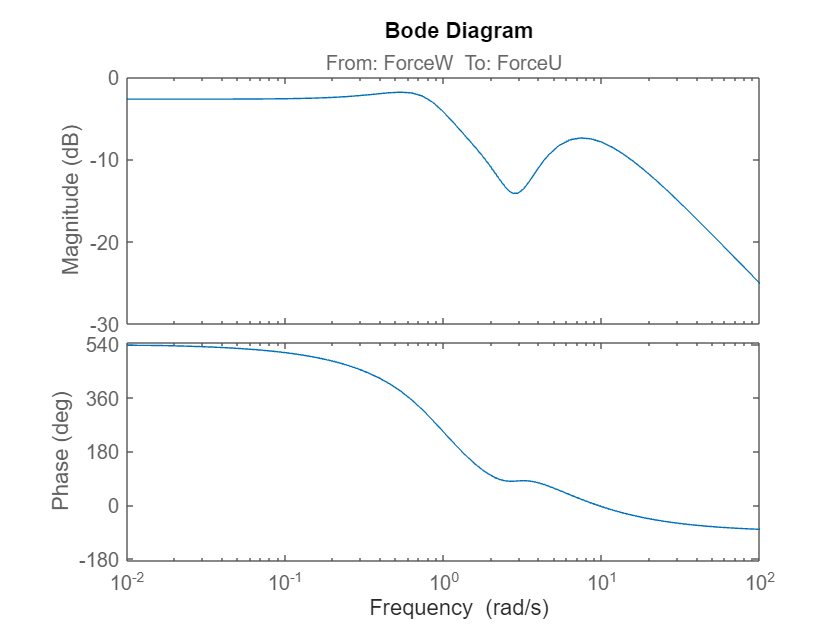

bode(ClLQ(7,2))

## `LQG`

% progetto filtro di Kalman
sys=ss(A,B(:,1),C(1,:),D(1,2));

Rk=sqrt(5e-2/3)/2/0.136

Rk = 0.4746

Qk=1e-3*eye(6)

Qk = 1.0e-03 *

    1.0000         0         0         0         0         0
         0    1.0000         0         0         0         0
         0         0    1.0000         0         0         0
         0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000


sys4Kalman=ss(A,[B(:,1) eye(6)],C(1,:),[D(1,1) zeros(1,6)]);
[kalmf,Lk,Pk] = kalman(sys4Kalman,Qk,Rk);
norm(Lk)

ans = 0.0342

eig(kalmf)

ans =   -2.8525 + 3.8453i
  -2.8525 - 3.8453i
  -0.3090 + 2.7900i
  -0.3090 - 2.7900i
  -0.0655 + 1.2953i
  -0.0655 - 1.2953i


AobsK=kalmf.A;
BobsK=kalmf.B;
CobsK=kalmf.C(1:end,:);
DobsK=kalmf.D(1:end,:);


## Hinf e Mixed Sensitivity

sysInf=ss(A,B(:,1),C(1,:),D(1,1));
Ws= zpk(makeweight(100,[0.8,1],1/100))

Ws =
 
  0.01 (s+80)
  -----------
   (s+0.008)
 
Continuous-time zero/pole/gain model.
Model Properties


Wt=zpk(makeweight(1/100,[0.8,1],100))

Wt =
 
  100 (s+0.008)
  -------------
     (s+80)
 
Continuous-time zero/pole/gain model.
Model Properties


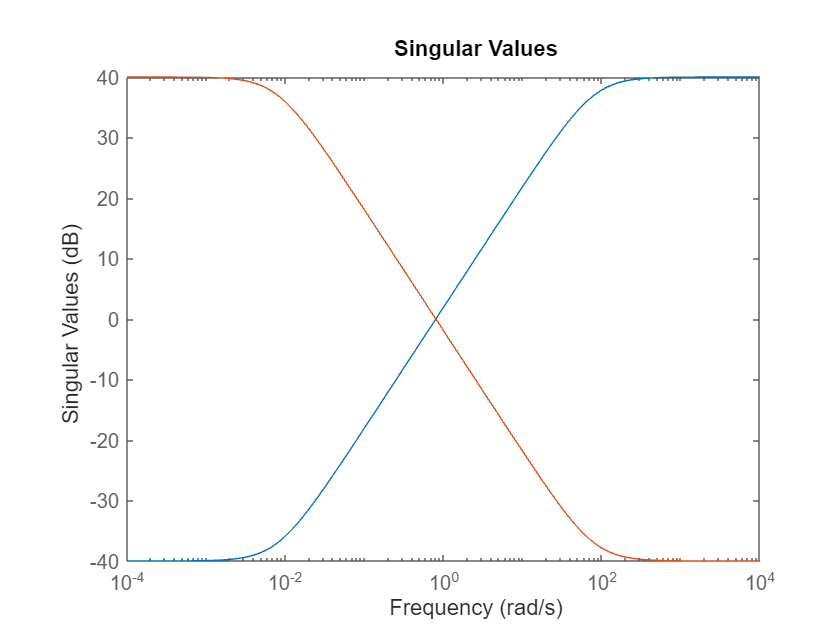

Wk=5;
sigma(Wt,Ws)

[Kinf,CL,gamma]=mixsyn(sysInf,Ws,Wk,Wt)

Kinf =
 
  A = 
               x1          x2          x3          x4          x5          x6          x7          x8
   x1      -0.008   9.539e-24   3.108e-16   8.621e-17  -1.334e-17   4.499e-18   1.906e-17   3.337e-17
   x2  -1.751e-17         -80       71.55    9.23e-18  -1.428e-18   4.816e-19    2.04e-18   3.572e-18
   x3  -1.887e-17     1.1e-24   3.586e-17           1  -1.539e-18    5.19e-19   2.198e-18   3.849e-18
   x4  -5.079e-19   2.962e-26          -5          -2           1         0.4   5.916e-20   1.036e-19
   x5   -6.37e-17   3.714e-24    1.21e-16   3.357e-17  -5.194e-18           1    7.42e-18   1.299e-17
   x6   -3.64e-17   2.122e-24       55.56       22.22      -24.44      -4.444       55.56   7.425e-18
   x7  -6.479e-18   3.778e-25   1.231e-17   3.414e-18  -5.282e-19   1.782e-19   7.547e-19           1
   x8        4.04   2.263e-05      -2.223      -2.597       1.038     -0.1445      -7.955      -1.387
 
  B = 
               u1
   x1       1.118
   x2   2.377e-17
   

gamma = 6.8521

Linf=sysInf*Kinf;
S=1/(1+Linf);
T=minreal(Linf*S);

22 states removed.


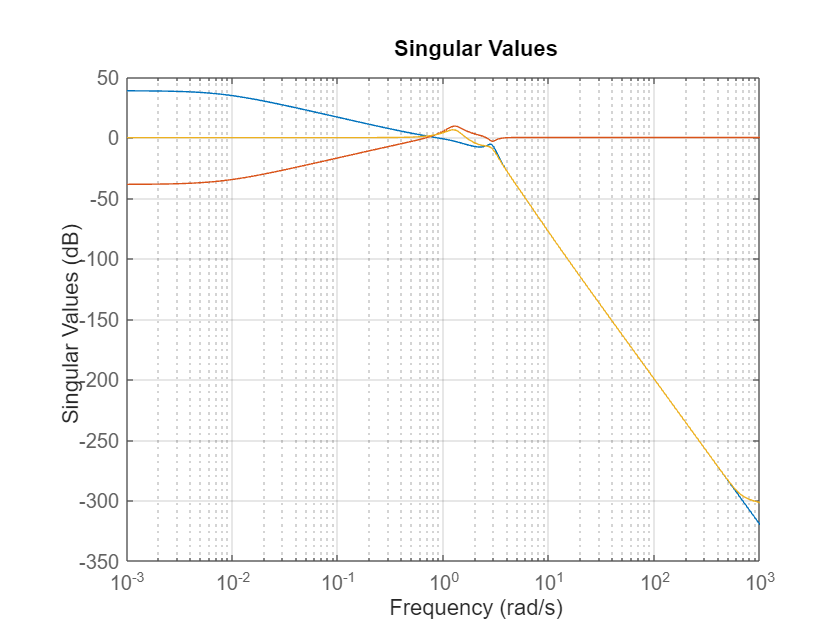

sigma(Linf,S,T)
grid

[Ak,Bk,Ck,Dk]=ssdata(Kinf)

Ak =    -0.0080    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0000  -80.0000   71.5506    0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0000    0.0000    0.0000    1.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0000    0.0000   -5.0000   -2.0000    1.0000    0.4000    0.0000    0.0000
   -0.0000    0.0000    0.0000    0.0000   -0.0000    1.0000    0.0000    0.0000
   -0.0000    0.0000   55.5556   22.2222  -24.4444   -4.4444   55.5556    0.0000
   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    1.0000
    4.0402    0.0000   -2.2228   -2.5969    1.0379   -0.1445   -7.9554   -1.3867


Bk =     1.1180
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
   -0.0000


Ck =     1.0101    0.0000   -0.5557   -0.6492    0.0928   -0.0361   -0.1555   -0.3467


Dk = 0

[z,p,k]=zpkdata(Kinf)

z = 1×1 cell array
    {7×1 double}


p = 1×1 cell array
    {8×1 double}


k = 1.1292

p{1}

ans =   -2.8506 + 3.8716i
  -2.8506 - 3.8716i
  -0.2611 + 2.8765i
  -0.2611 - 2.8765i
  -0.0080 + 0.0000i
  -0.8038 + 1.1177i
  -0.8038 - 1.1177i
 -80.0000 + 0.0000i


%sposto polo in 0.01 nell'origine
p1=p;
p1{1}

ans =   -2.8506 + 3.8716i
  -2.8506 - 3.8716i
  -0.2611 + 2.8765i
  -0.2611 - 2.8765i
  -0.0080 + 0.0000i
  -0.8038 + 1.1177i
  -0.8038 - 1.1177i
 -80.0000 + 0.0000i


p1{1}(5)=0;

Kinf1=ss(zpk(z,p1,k));
[Ak1,Bk1,Ck1,Dk1]=ssdata(zpk(z,p1,k));
L1=sysInf*Kinf1;
S1=minreal(1/(1+L1));

8 states removed.


T1=minreal(L1*S1)

14 states removed.

T1 =
 
  A = 
             x1        x2        x3        x4        x5        x6        x7
   x1   -0.4571   -0.3879   -0.2212   -0.1645   -0.1588    0.1306  -0.09139
   x2    -2.073    -3.036    -2.773   -0.4866  -0.04735  -0.09694  -0.04224
   x3    0.3403     2.983    0.3636   -0.5222  -0.02941   0.08826  -0.04202
   x4      1.14     1.099     2.939    0.4726     1.249    0.1619    -0.035
   x5    -1.244     2.245     -4.43    -5.525   -0.2165      2.03   -0.1078
   x6   -0.4838    -1.207    0.8789     2.008    -2.049    -4.621     5.393
   x7     1.162     3.062    0.3008    -1.872     1.275    -2.006   -0.3366
 
  B = 
            u1
   x1   -4.331
   x2   -6.556
   x3   -7.343
   x4  -0.8062
   x5   -3.973
   x6   -1.135
   x7    5.121
 
  C = 
              x1         x2         x3         x4         x5         x6         x7
   y1    -0.0581    0.01998    0.01485   0.005176     -0.004   -0.00306  -0.005235
 
  D = 
       u1
   y1   0
 
Continuous-time state-s

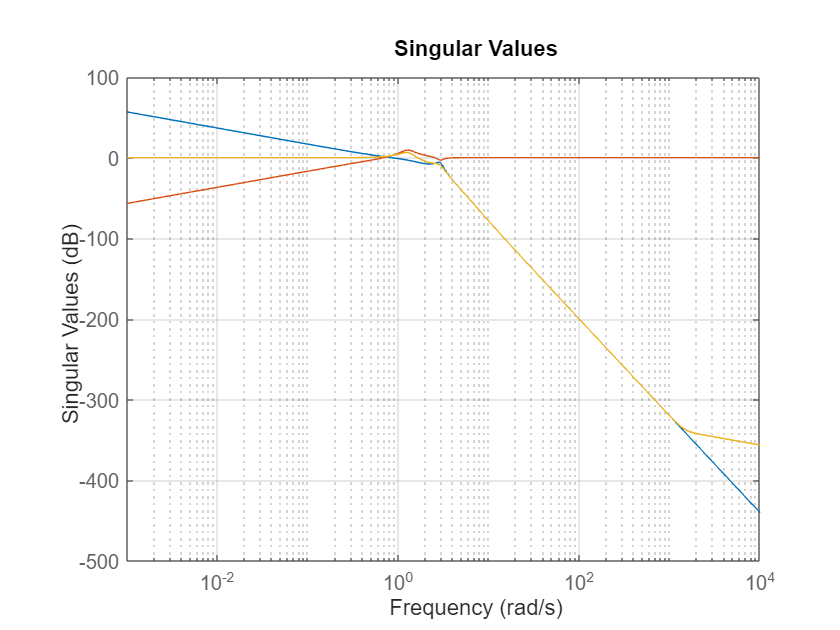

sigma(L1,S1,T1, {1e-3,1e4})
grid

## Funzione a ciclo chiuso

function clLoop=closedLoop(A,B,C,D,Kaum)
G=ss(A,B,C,D);
G.InputName={'ForceU','ForceW'};
G.OutputName={'Pos1','Vel1','Pos_ruota', 'Vel_ruota','Pos2','Vel2'};

Ki=Kaum(1,7);

sysItg=ss(0,1,Ki,0);
sysItg.InputName='errorPos1';
sysItg.OutputName='IntegralAction';


Kf=Kaum(:,1:6);
StFeedMatrix=ss([],[],[],Kf);
StFeedMatrix.InputName={'Pos1','Vel1','Pos_ruota', 'Vel_ruota','Pos2','Vel2'};
StFeedMatrix.OutputName='StateFeedbackAction';


Sum1=sumblk('errorPos1=Ref-Pos1');
Sum2=sumblk('ForceU=-IntegralAction-StateFeedbackAction');
clLoop=connect(G,sysItg,StFeedMatrix,Sum1,Sum2,{'Ref','ForceW'},{'Pos1','Vel1','Pos_ruota', 'Vel_ruota','Pos2','Vel2','ForceU'});
end
